clear; clc;

**Part 1 OFDM signal generation and reception**


%% Parameters
Nfft = 64;                 % FFT size
CP = 16;                % Cyclic prefix size
Fs = 20e6;              % Sampling rate (Hz)
Ts = 1/Fs;              % Sampling period

pilotBins = [12, 26, 40, 54]; 
active_subcarriers = [7:32, 34:59]; % total of 52 indices
dataBins = setdiff(active_subcarriers, pilotBins);

pilot_bits = randi([0 1], length(pilotBins), 1);
pilot_mod = 2*pilot_bits - 1; 

numDataBits = length(dataBins)*4;
data_bits = randi([0 1], numDataBits, 1);
data_bits_matrix = reshape(data_bits, 4, []).';% Reshape bits into groups of 4 (each symbol)
data_symbols = bi2de(data_bits_matrix, 'left-msb');
M = 16;  % Modulation order for 16-QAM
% data_mod = qammod(data_symbols, M, 'UnitAveragePower', true);
data_mod = qammod(data_symbols, M, 'gray');
ofdm_symbol_freq = zeros(Nfft,1);
ofdm_symbol_freq(pilotBins) = pilot_mod;
ofdm_symbol_freq(dataBins)  = data_mod;


(1) Plot the magnitude of the frequency spectrum for the OFDM symbol with the 0 subcarrier in the center and the correct frequency unit in MHz. Also, use a different color for the pilot tones.

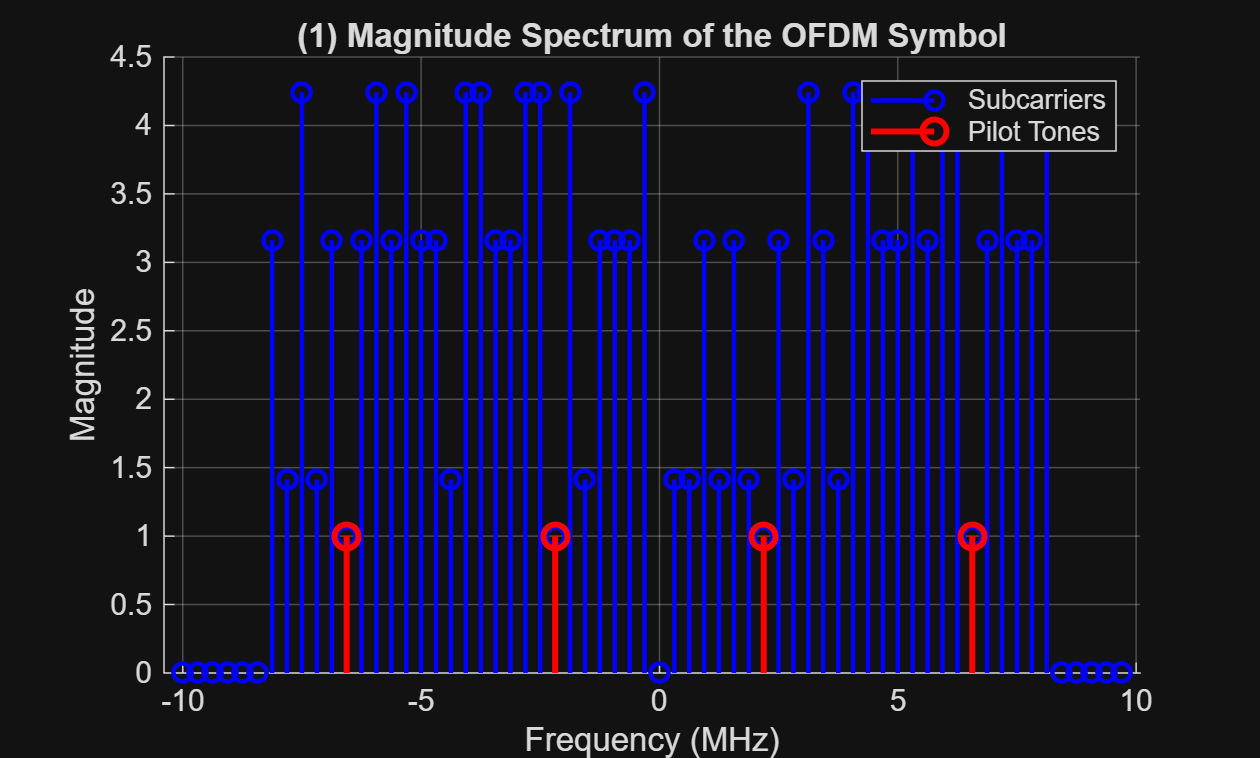

%% (1) Plot Magnitude of Frequency Spectrum
freq_axis = ((-Nfft/2):(Nfft/2-1))*(Fs/Nfft)/1e6;  % in MHz

% Compute shifted spectrum for plotting (DC at center)
% ofdm_symbol_freq_shifted = fftshift(ofdm_symbol_freq);
figure;
hold on;
% Plot magnitude of all subcarriers
stem(freq_axis, abs(ofdm_symbol_freq), 'b', 'LineWidth', 1.5);

pilotBins_shifted = zeros(size(pilotBins));
for idx = 1:length(pilotBins)
    if pilotBins(idx) <= Nfft/2
        pilotBins_shifted(idx) = pilotBins(idx) + Nfft/2;
    else
        pilotBins_shifted(idx) = pilotBins(idx) - Nfft/2;
    end
end
% Plot pilot tone magnitudes
stem(freq_axis(pilotBins), abs(ofdm_symbol_freq(pilotBins)), 'ro', 'MarkerSize', 8, 'LineWidth',2);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('(1) Magnitude Spectrum of the OFDM Symbol');
legend('Subcarriers','Pilot Tones');
grid on;
hold off;

## (2) Following (1), what is the subcarrier spacing, i.e., the frequency difference between two adjacent subcarriers?

subcarrier_spacing = Fs/Nfft; 
fprintf('(2) Subcarrier spacing: %.2f kHz\n', subcarrier_spacing / 1e3);

(2) Subcarrier spacing: 312.50 kHz


(3) Perform IFFT to obtain the OFDM symbol in the time domain, i.e., signal (a). Please ensure

you correctly shift the frequency before performing IFFT (you should not perform IFFT when

the 0 subcarrier is in the middle). Please plot both the real and imaginary parts of the OFDM

time domain signal with the correct time unit in microseconds.

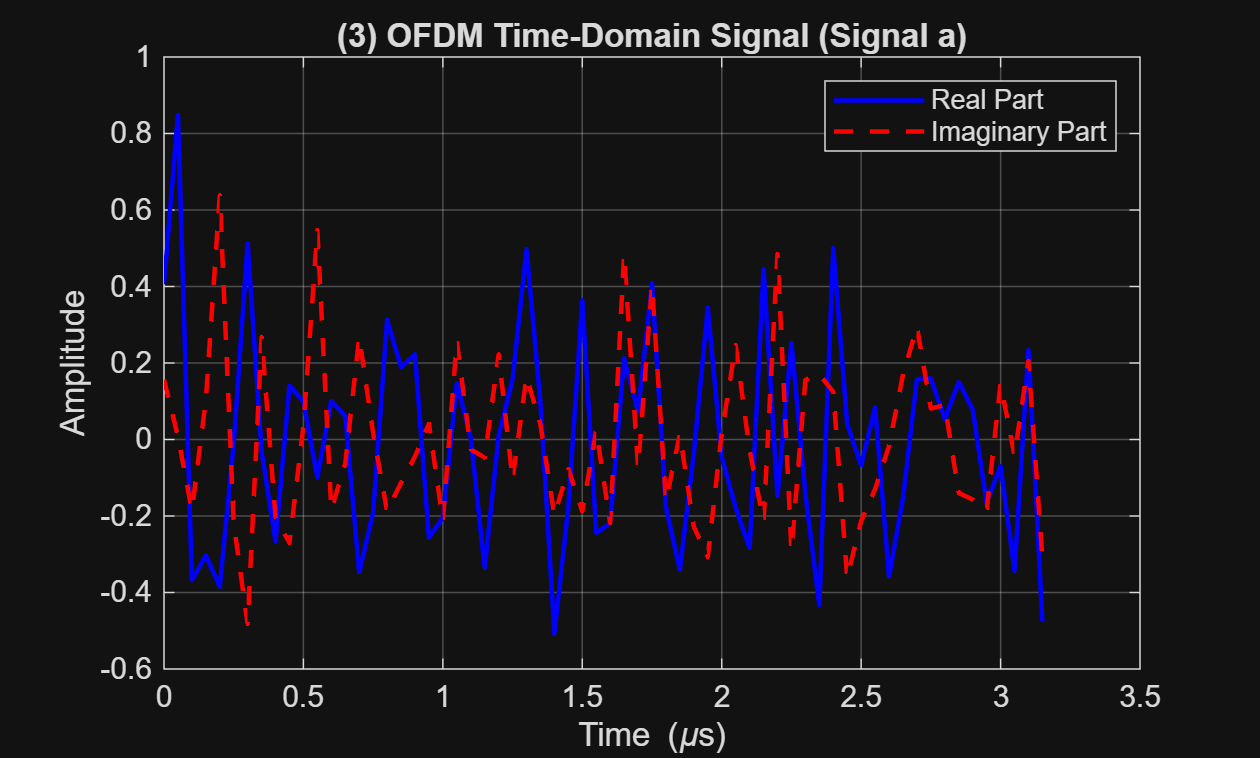

%% (3) Perform IFFT and Plot Time Domain Signal

ofdm_symbol_freq_centered = fftshift(ofdm_symbol_freq);  % now DC is at center
ofdm_symbol_time = ifft(ifftshift(ofdm_symbol_freq_centered), Nfft);
t = (0:Nfft-1)/Fs*1e6;  % in microseconds

figure;
plot(t, real(ofdm_symbol_time), 'b-', 'LineWidth', 1.5);
hold on;
plot(t, imag(ofdm_symbol_time), 'r--', 'LineWidth', 1.5);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('(3) OFDM Time-Domain Signal (Signal a)');
legend('Real Part','Imaginary Part');
grid on;
hold off;

## (4) Add the cyclic prefix to signal (a) to obtain signal (b). Plot signal (b) in the time domain, for both the real and imaginary parts, with clear legend and correct time unit. Also, mark the part of the cyclic prefix in the plot.

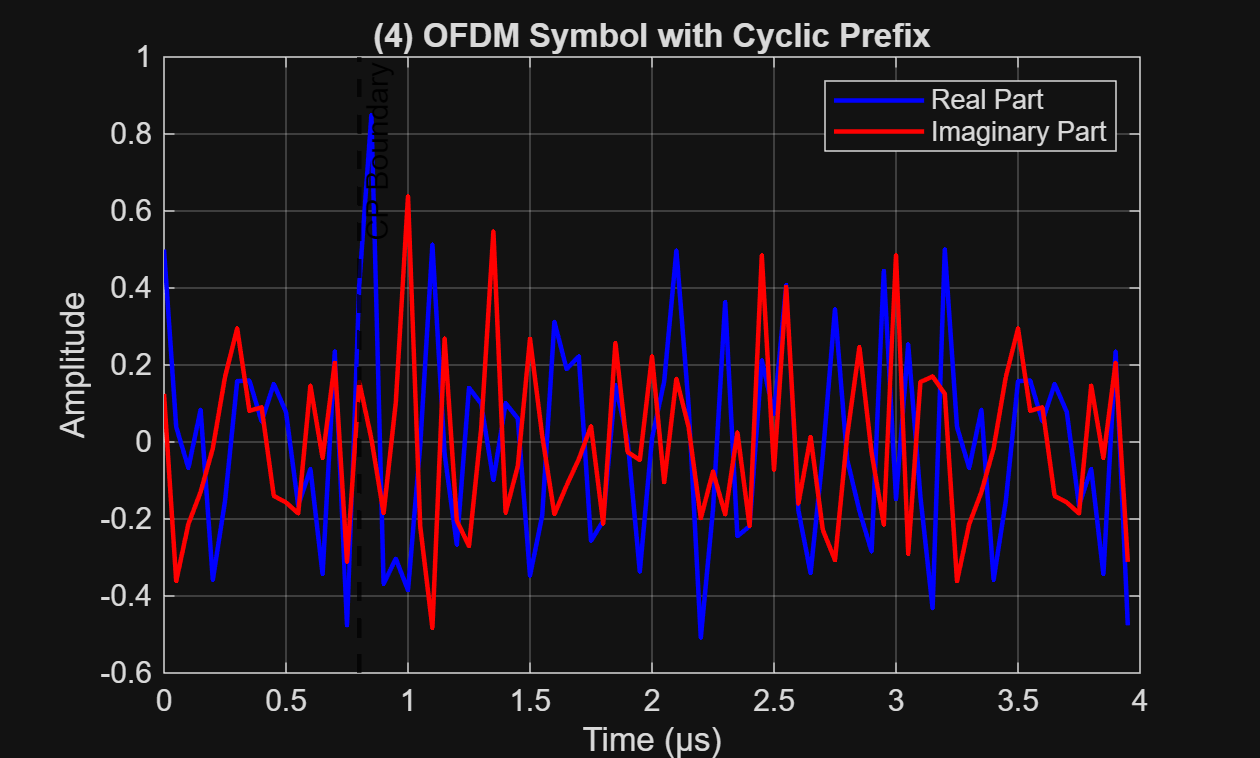


ofdm_symbol_cp = [ofdm_symbol_time(end-CP+1:end); ofdm_symbol_time];
time_axis_cp = (0:length(ofdm_symbol_cp)-1)/Fs*1e6;  % in microseconds

figure;
plot(time_axis_cp, real(ofdm_symbol_cp), 'b', 'LineWidth', 1.5);
hold on;
plot(time_axis_cp, imag(ofdm_symbol_cp), 'r', 'LineWidth', 1.5);
xline(Ts * CP * 1e6, '--k', 'CP Boundary', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Time (μs)'); ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
title('(4) OFDM Symbol with Cyclic Prefix');

(5) Following (4), what is the duration of this OFDM symbol with the cyclic prefix? What is the

duration of the OFDM symbol without the cyclic prefix?

with CP: 4μs, no CP: 3.2 CP

%% (5) Compute OFDM Symbol Duration
T_ofdm = Nfft * Ts * 1e6;
T_ofdm_cp = (Nfft + CP) * Ts * 1e6;
fprintf('(5) OFDM symbol duration without CP: %.2f μs\n', T_ofdm);

(5) OFDM symbol duration without CP: 3.20 μs


fprintf('OFDM symbol duration with CP: %.2f μs\n', T_ofdm_cp);

OFDM symbol duration with CP: 4.00 μs


(6) Assume the channel is noiseless. Remove the cyclic prefix at the receiver to obtain signal (c).

Plot the real part of (c) and (a) on the same plot to show the cyclic prefix is correctly removed.

As before, add the legend and mark the axis with the correct time unit.

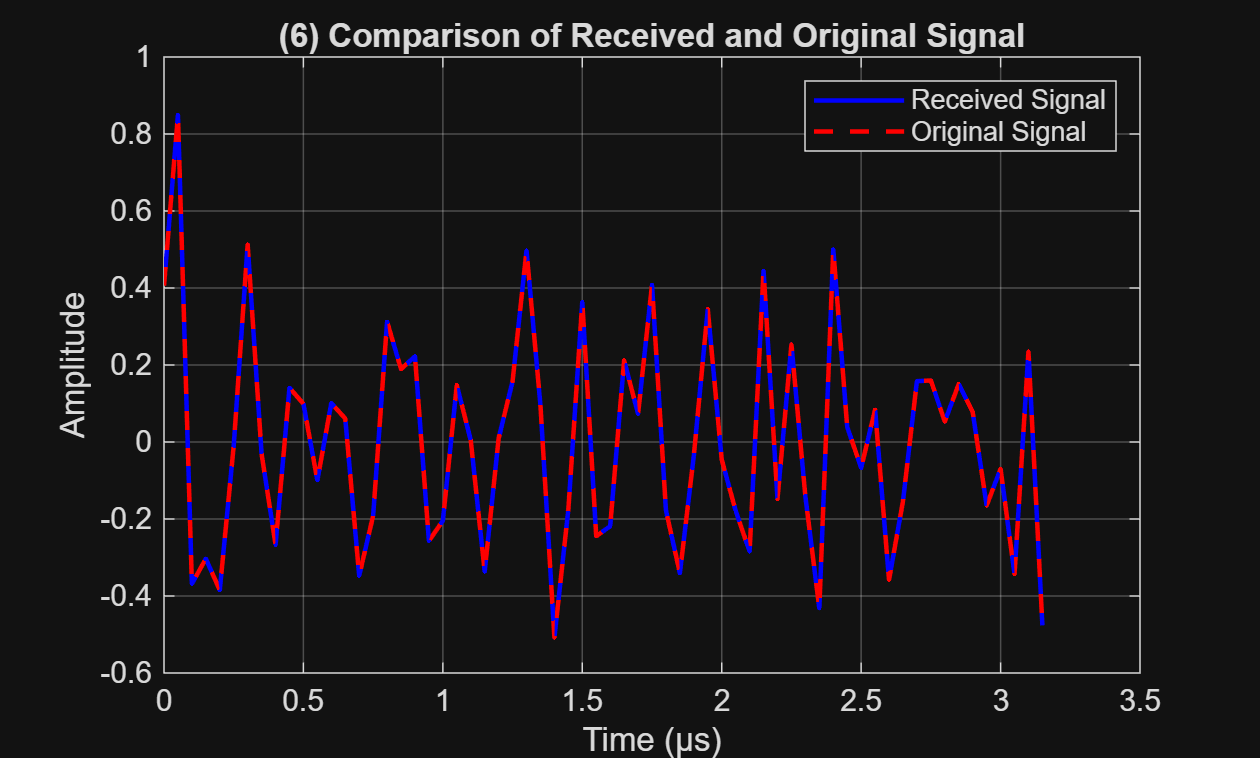

%% (6) Remove Cyclic Prefix and Compare
rx_noCP = ofdm_symbol_cp(CP+1:end);
figure;
plot(t, real(rx_noCP), 'b', 'LineWidth', 1.5);
hold on;
plot(t, real(ofdm_symbol_time), 'r--', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Time (μs)'); ylabel('Amplitude');
legend('Received Signal', 'Original Signal');
title('(6) Comparison of Received and Original Signal');

(7) Perform FFT to signal (c) to obtain the received symbols of each subcarrier. In the same figure,

plot the magnitude of the frequency spectrum of both the received and the transmitted OFDM

symbol to show they are identical. As before, have the 0 subcarrier in the center, add the

legend, and mark the axis with the correct frequency unit.

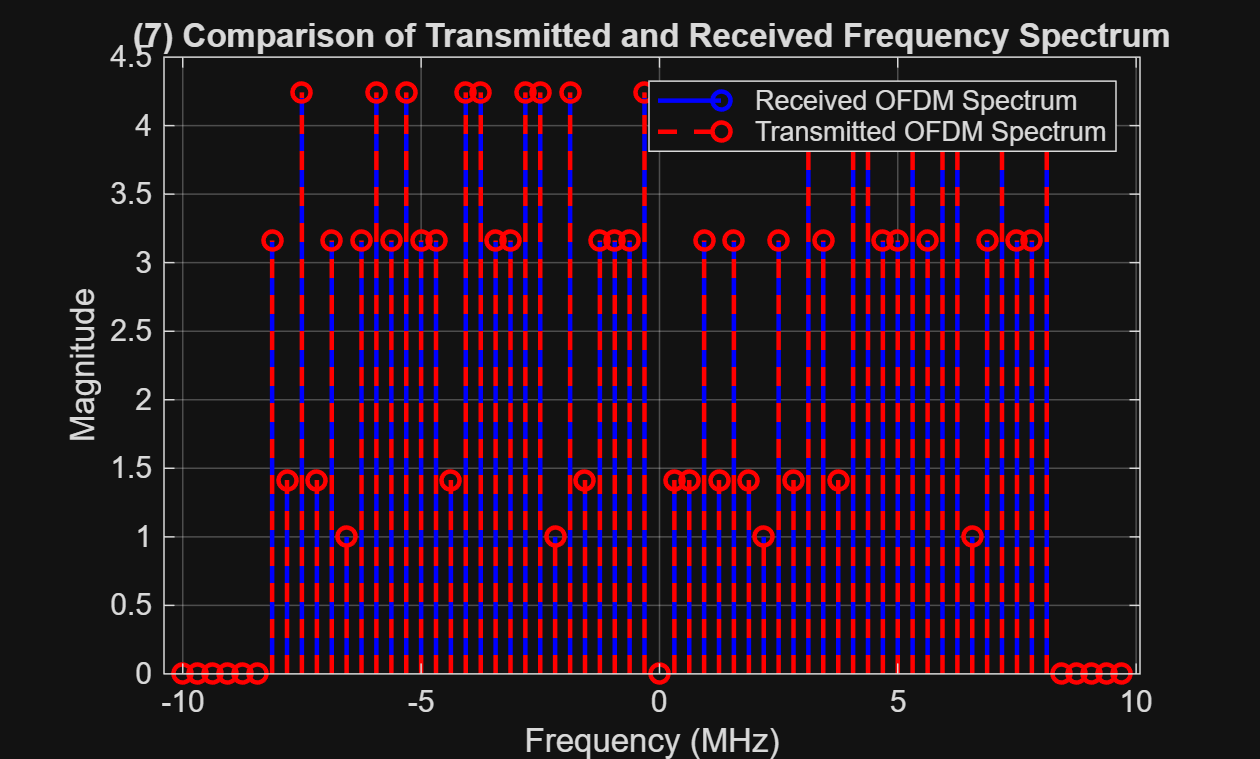

%% (7) Perform FFT and Compare Frequency Spectra
X_rx = fft(rx_noCP);
% X_rx = fftshift(fft(rx_noCP));

figure;
stem(freq_axis, abs(X_rx), 'b', 'LineWidth', 1.5);
hold on;
stem(freq_axis, abs(ofdm_symbol_freq), 'r--', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (MHz)'); ylabel('Magnitude');
legend('Received OFDM Spectrum', 'Transmitted OFDM Spectrum');
title('(7) Comparison of Transmitted and Received Frequency Spectrum');

(8) Generate 1000 different OFDM symbols. For the time domain waveform, what is the peak power, and what is the average power? As a result, what is the Peak-to-Average Power Ratio (PAPR)?

%% (8) Compute PAPR
num_symbols = 1000;

ofdm_symbol_time = zeros(num_symbols,Nfft);
ofdm_symbol_cp = zeros(num_symbols, Nfft + CP);
data_mod = zeros(num_symbols, length(dataBins));
data_symbols = zeros(num_symbols, length(dataBins));
ofdm_symbol_freq = zeros(num_symbols,Nfft);

peak_power = zeros(num_symbols, 1);
avg_power = zeros(num_symbols, 1);

for k = 1:num_symbols

    pilot_bits = randi([0 1], length(pilotBins), 1);
    pilot_mod = 2*pilot_bits - 1; 
    
    numDataBits = length(dataBins)*4;
    data_bits = randi([0 1], numDataBits, 1);
    data_bits_matrix = reshape(data_bits, 4, []).';% Reshape bits into groups of 4 (each symbol)
    data_symbols(k,:) = bi2de(data_bits_matrix, 'left-msb');
    M = 16;  % Modulation order for 16-QAM
    % data_mod(k,:) = qammod(data_symbols(k,:), M, 'UnitAveragePower', true);
    data_mod(k,:) = qammod(data_symbols(k,:), M, 'gray');
    % ofdm_symbol_freq = zeros(Nfft,1);
    ofdm_symbol_freq(k,pilotBins) = pilot_mod;
    ofdm_symbol_freq(k,dataBins)  = data_mod(k,:);
    
    ofdm_symbol_freq_centered = fftshift(ofdm_symbol_freq(k,:));  % now DC is at center
    % ofdm_symbol_time(k,:) = ifft(ifftshift(ofdm_symbol_freq_centered), Nfft);
    ofdm_symbol_time(k,:) = ifft(ofdm_symbol_freq(k,:), Nfft);
    ofdm_symbol_cp(k,:) = [ofdm_symbol_time(k,end-CP+1:end), ofdm_symbol_time(k,1:Nfft)];
    
    peak_power(k) = max(abs(ofdm_symbol_cp(k,:).^2));
    avg_power(k) = mean(abs(ofdm_symbol_cp(k,:).^2));

end


PAPR = 10*log10(max(peak_power) / mean(avg_power));
fprintf('(8) Peak Power: %.2f\nAverage Power: %.2f\nPAPR: %.2f dB\n', max(peak_power), mean(avg_power), PAPR);

(8) Peak Power: 1.28
Average Power: 0.12
PAPR: 10.35 dB


(9) Transmit and receive 1000 different OFDM symbols with SNR = 15dB. Plot the constellation

diagram for the received symbols.

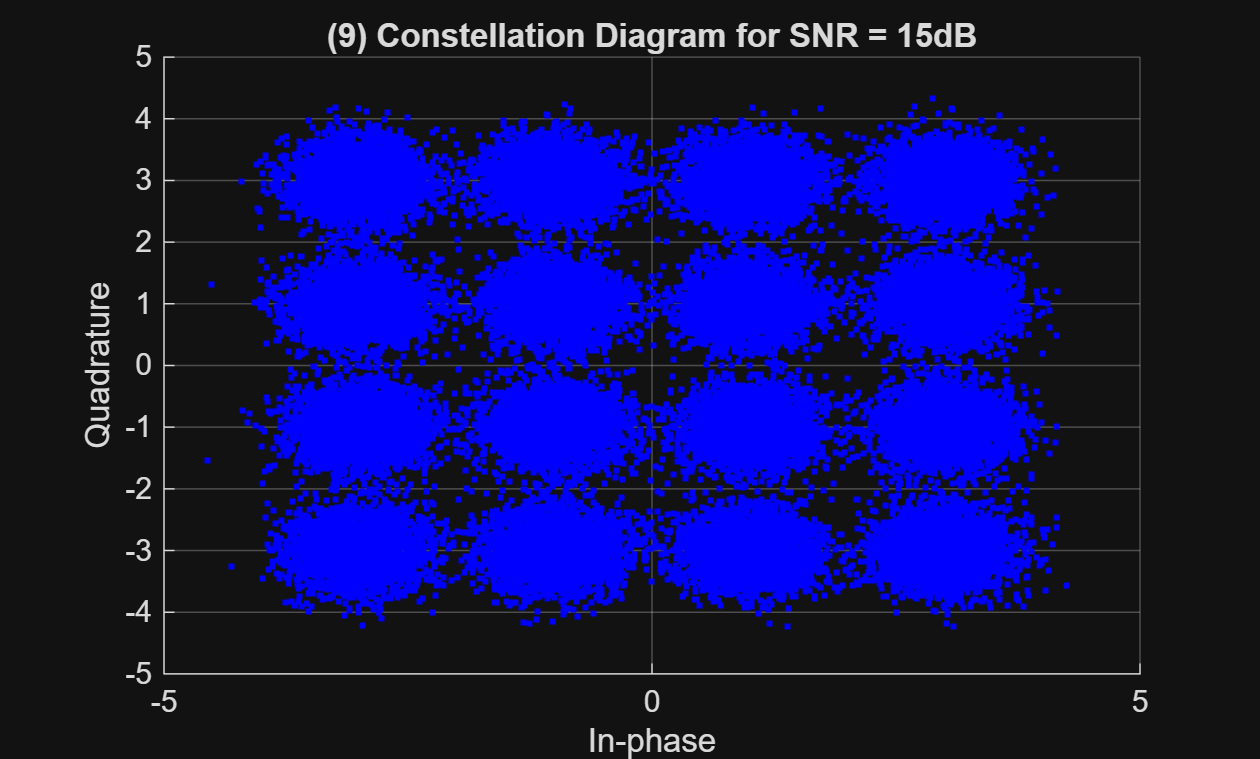

%% (9) Transmit & Receive with SNR = 15dB

snr_dB = 15;
snr_linear = 10^(snr_dB/10);
rx_data_all = [];
for k = 1:num_symbols
    noise_power = mean(abs(ofdm_symbol_cp(k,:)).^2) / snr_linear;
    noise = sqrt(noise_power/2) * (randn(size(ofdm_symbol_cp(k,:))) + 1j*randn(size(ofdm_symbol_cp(k,:))));
    y_cp = ofdm_symbol_cp(k,:) + noise;
    y_time = y_cp(CP+1:end);
    Y = fft(y_time, Nfft);
    rx_data_all = [rx_data_all; Y(dataBins)];
end


figure;
scatter(real(rx_data_all), imag(rx_data_all), 'b.');
grid on;
xlabel('In-phase'); ylabel('Quadrature');
title('(9) Constellation Diagram for SNR = 15dB');

(10) Following (8), calculate the SNR using the 1000 OFDM symbols and confirm that it is close to

15 dB.

%% (10) Compute SNR from Received Symbols
received_power = mean(abs(rx_data_all(:)).^2);
noise_power = received_power / (10^(15/10));
computed_SNR = 10*log10(received_power / noise_power);
fprintf('(10) Computed SNR: %.2f dB\n', computed_SNR);

(10) Computed SNR: 15.00 dB


(11) Transmit and receive 1000 different OFDM symbols with SNR = {0dB, 5dB, 10dB, 15dB} and

calculate the BER for the data tones. Plot the BER vs SNR. Briefly describe the figure.

BER decreases exponentially as SNR increases. 

因為SNR 越大，noise影響力越小，BER就越小

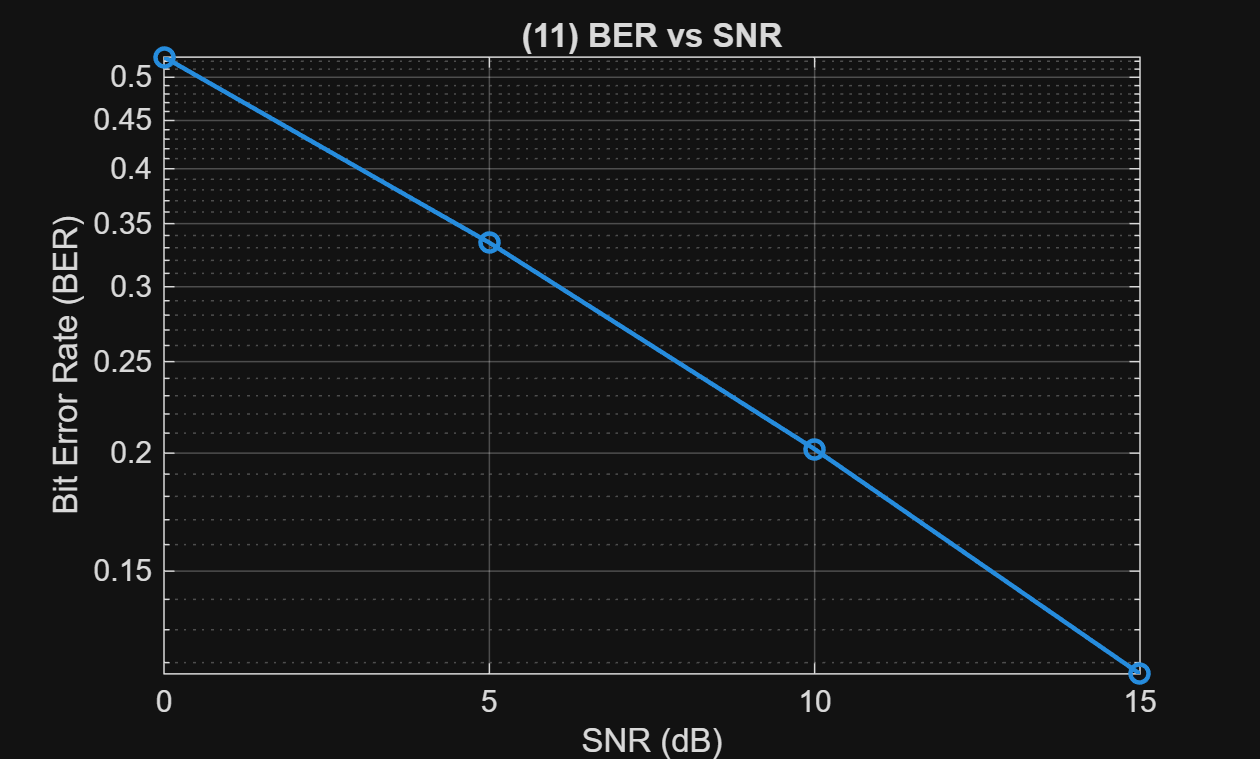

%% (11) BER vs SNR
SNR_values = [0, 5, 10, 15];
BER = zeros(size(SNR_values));
for i = 1:length(SNR_values)

    y_cp_noisy = awgn(ofdm_symbol_cp, SNR_values(i), 'measured');
    y_time_noisy = y_cp_noisy(:,CP+1:end);
    rx_bits = qamdemod(y_time_noisy, M, 'UnitAveragePower', true);
    tx_bits = qamdemod(ofdm_symbol_time, M, 'UnitAveragePower', true);

    BER(i) = sum(rx_bits(:) ~= tx_bits(:)) / numel(tx_bits);

end

figure;
semilogy(SNR_values, BER, '-o', 'LineWidth', 1.5);
grid on;
xlabel('SNR (dB)'); ylabel('Bit Error Rate (BER)');
title('(11) BER vs SNR');

**[Part 2] STS & LTS generation and frame synchronization**

(1) Generate the short training sequence (STS). Please refer to S_{-26,26} in the course slide for STS

generation. Plot the STS (10 repeated symbols) in the time domain with the x-axis in 𝜇𝑆.

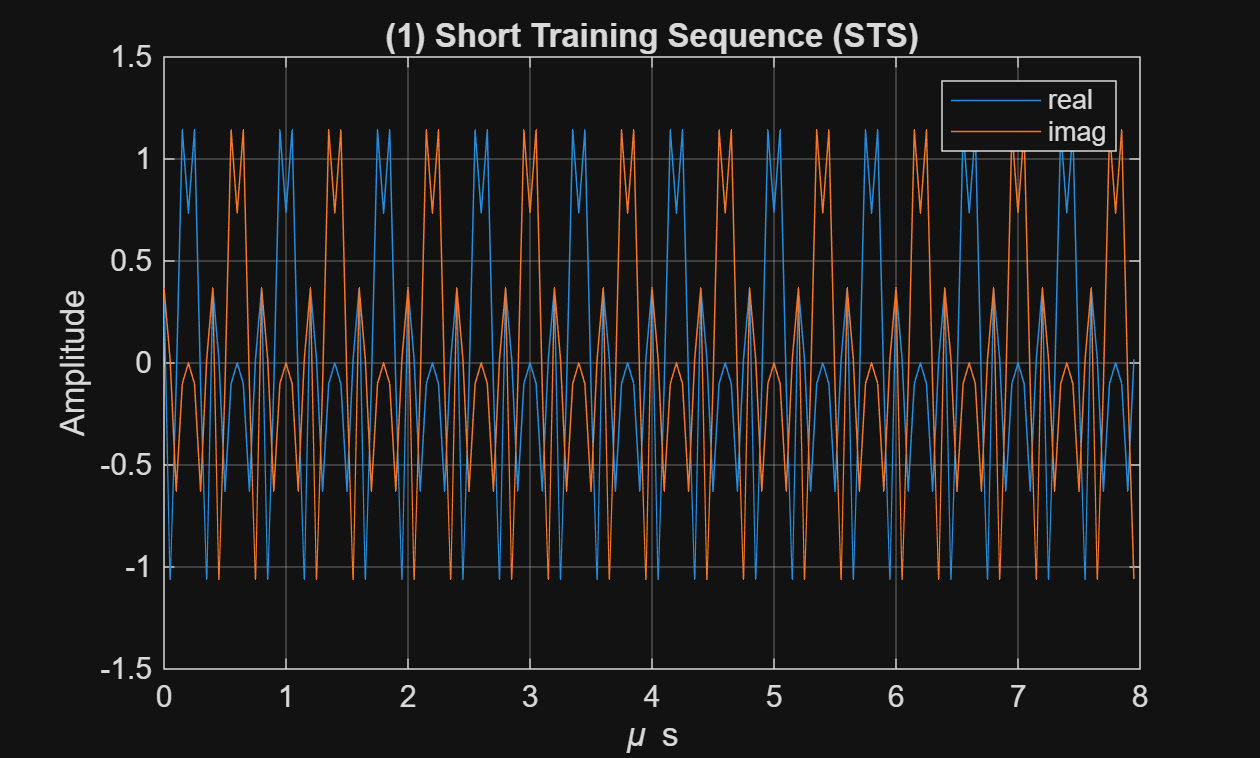

%% (1) Generate Short Training Sequence (STS)
N = 64; % FFT size
STS_freq = zeros(1, N);
index = 7:59; 
STS_freq(index) = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, 1+1j, 0, 0, 0,0, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0,0, 1+1j, ...
                                0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
STS_time = ifft(ifftshift(STS_freq), N) * sqrt(N);
STS_rep = repmat(STS_time(1:16), 1, 10); % 10 repeated symbols

% Plot STS
figure;
t = (0:length(STS_rep)-1) * (1/20); % x-axis in microseconds
plot(t, real(STS_rep)); hold on;
plot(t, imag(STS_rep));
title('(1) Short Training Sequence (STS)'); xlabel('\mu s'); ylabel('Amplitude'); 
legend("real", "imag");
grid on;

(2) Generate the long training sequence (LTS). Please refer to L_{-26,26} in the course slide for LTS

generation. Plot the LTS (2 long training symbols + cyclic prefix as in the course slide) in the

time domain with the x-axis in 𝜇𝑆.

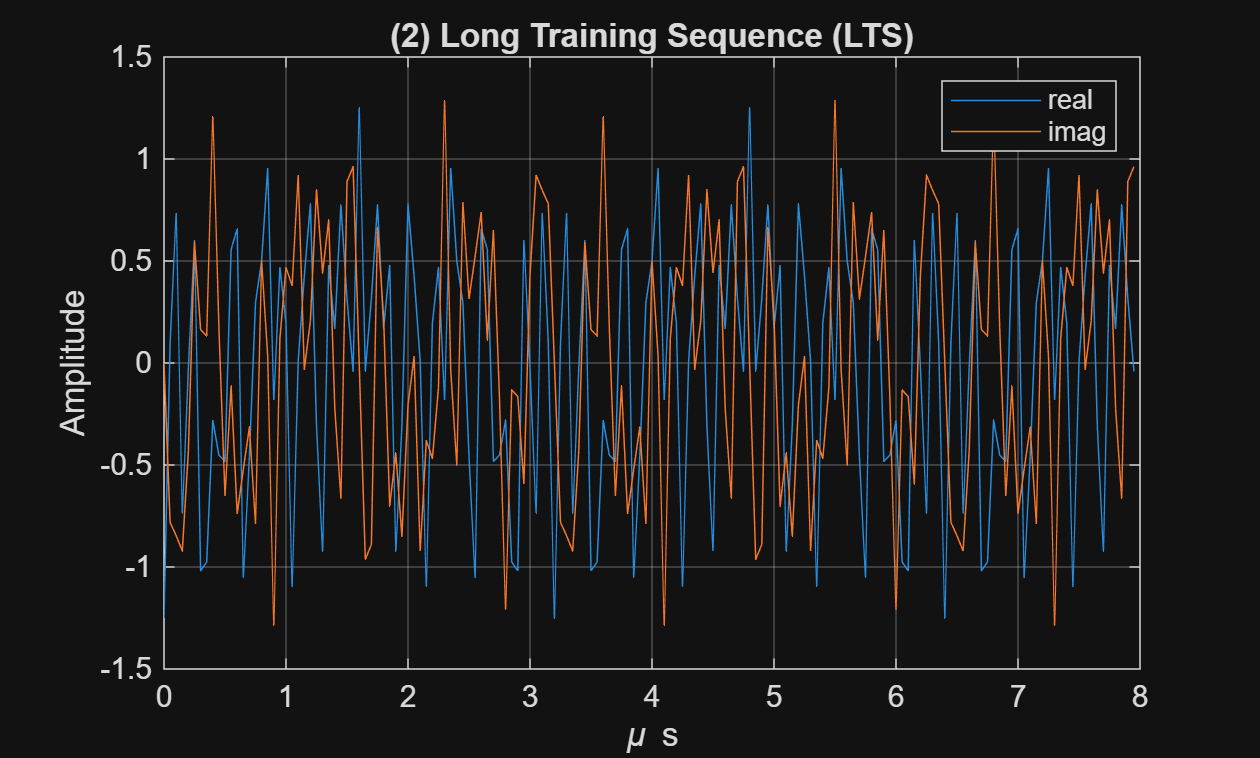

%% (2) Generate Long Training Sequence (LTS)

LTS_freq = zeros(1, N);
LTS_freq(index) = [1,1,-1,-1, 1,1,-1,1, -1,1,1,1, 1,1,1,-1, -1,1,1,-1, 1,-1,1,1, 1,1,0,...
                  1,-1, -1,1,1,-1, 1,-1,1,-1, -1,-1,-1,-1, 1,1,-1,-1, 1,-1,1,-1, 1,1,1,1,];
LTS_time = ifft(ifftshift(LTS_freq), N) * sqrt(N);
LTS_cp = LTS_time(33:64); % Cyclic prefix
LTS_rep = [LTS_cp, LTS_time, LTS_time];

figure;
t = (0:length(LTS_rep)-1) * (1/20);
plot(t, real(LTS_rep)); hold on;
plot(t, imag(LTS_rep));
legend("real", "imag");
title('(2) Long Training Sequence (LTS)'); xlabel('\mu s'); ylabel('Amplitude'); grid on;

(3) Create a frame starting with STS, LTS, followed by 5 OFDM symbols (using the same

procedure in part 1 with 16-QAM). Normalize the signal if needed so that the whole frame has

consistent power. Plot the whole frame in the time domain with the x-axis in 𝜇𝑆. Mark STS,

LTS, and data portion in the frame.

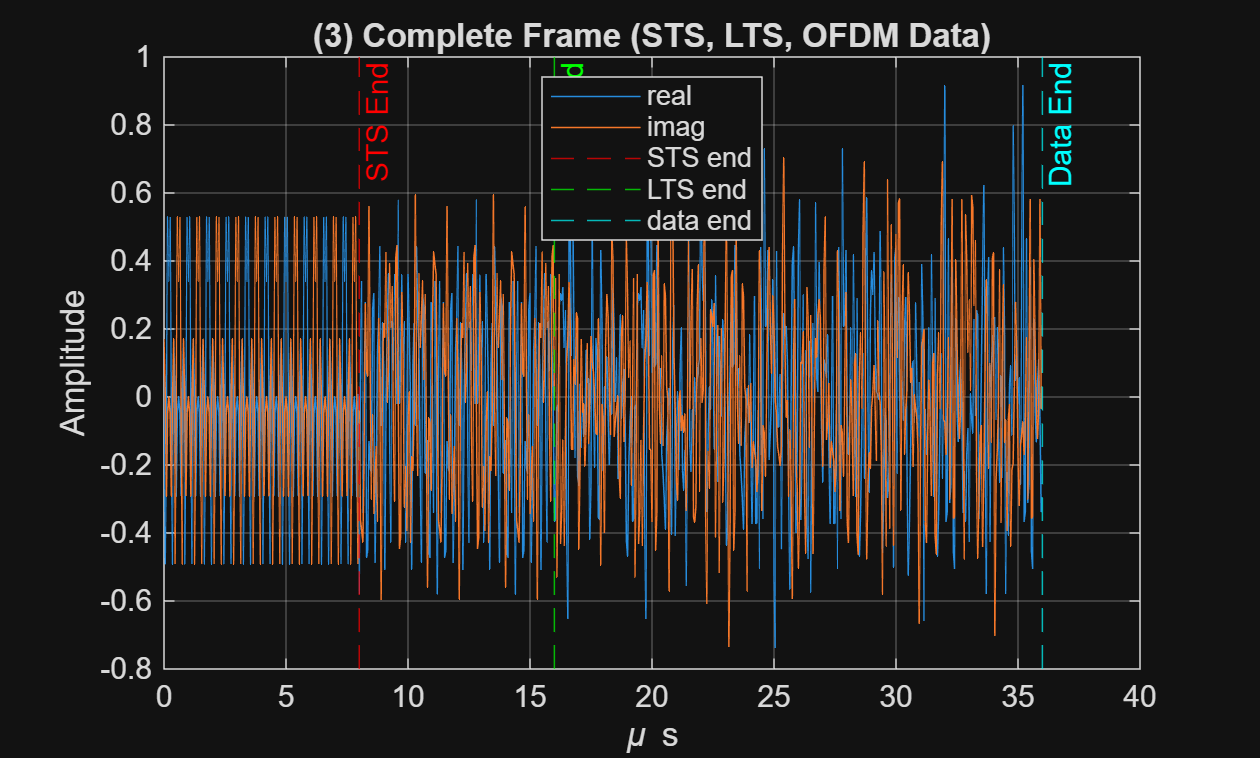

%% (3) Create Frame with STS, LTS, and OFDM Data

M = 16; % 16-QAM
num_symbols = 5;
QAM_data = randi([0 M-1], 53, num_symbols); % Random 16-QAM symbols
QAM_mod = qammod(QAM_data, M, 'UnitAveragePower', true); % Normalize power
OFDM_freq = zeros(N, num_symbols);
OFDM_freq(index, :) = QAM_mod;
OFDM_freq(33,:) = 0;
OFDM_time = ifft(ifftshift(OFDM_freq, 1), N, 1) * sqrt(N);
OFDM_cp = OFDM_time(49:64, :); % Cyclic prefix for each OFDM symbol
OFDM_frame = [OFDM_cp; OFDM_time];

% Construct full frame
frame = [STS_rep, LTS_rep, OFDM_frame(:).'];
frame_normalized = frame / max(abs(frame)); % Normalize

% Plot full frame
figure;
t = (0:length(frame_normalized)-1) * (1/20);
plot(t, real(frame_normalized)); hold on;
plot(t, imag(frame_normalized));

title('(3) Complete Frame (STS, LTS, OFDM Data)'); xlabel('\mu s'); ylabel('Amplitude'); grid on;
xline(length(STS_rep)*(1/20), '--r', 'STS End');
xline((length(STS_rep)+length(LTS_rep))*(1/20), '--g', 'LTS End');
xline((length(STS_rep)+length(LTS_rep) + length(OFDM_frame(:)))*(1/20), '--c', 'Data End');
legend("real", "imag", "STS end", "LTS end", "data end", 'location','best');

(4) Create your own matched filter based procedure that detects the short training symbol to

correctly determine the start of the OFDM data symbols. Explain your synchronization

algorithm.

we find the first peak of the correlation signal to align the signal with zp

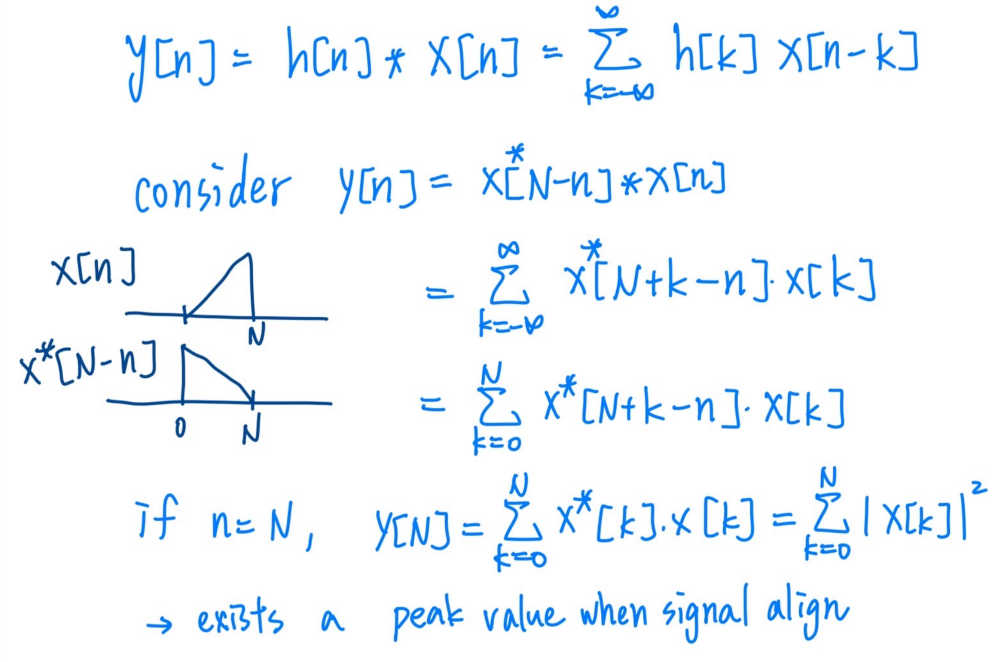

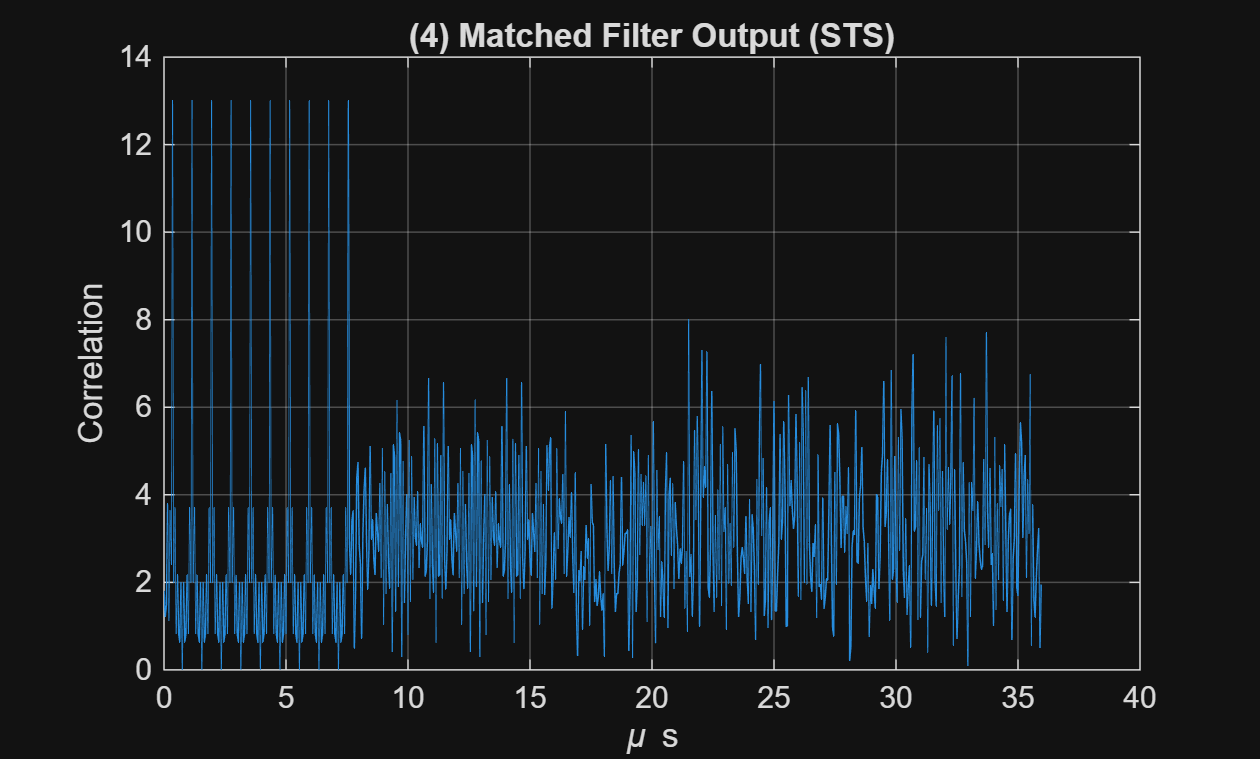

%% (4) Matched Filter for STS Detection
mf_sts = conj(flip(STS_time(1:16)));
correlation = abs(conv(frame, mf_sts, 'same'));

% Plot correlation result
figure;
t = (0:length(correlation)-1) * (1/20);
plot(t, correlation);
title('(4) Matched Filter Output (STS)'); xlabel('\mu s'); ylabel('Correlation'); grid on;

(5) Following (4), to show the correctness of your proposed procedure, let’s test your algorithm on

a zero-padded noiseless frame. Specifically, add 30 zeros before and after the created frame

(that is, the frame starts with 30 zeros, followed by STS, LTS, OFDM data, and then 30 zeros).

Next, apply your proposed algorithm in (4). Plot the match filter result and briefly explain the

figure. Does your algorithm correctly identify the beginning of the frame and, thus, the

beginning of each OFDM symbol?

both the beginning of  the first peak and the ofdm signal are marked on the figure. moreover, the result of ideal and detected are the same. thus, both the beginning of the frame and the beginning of each OFDM symbol are correctly detected.

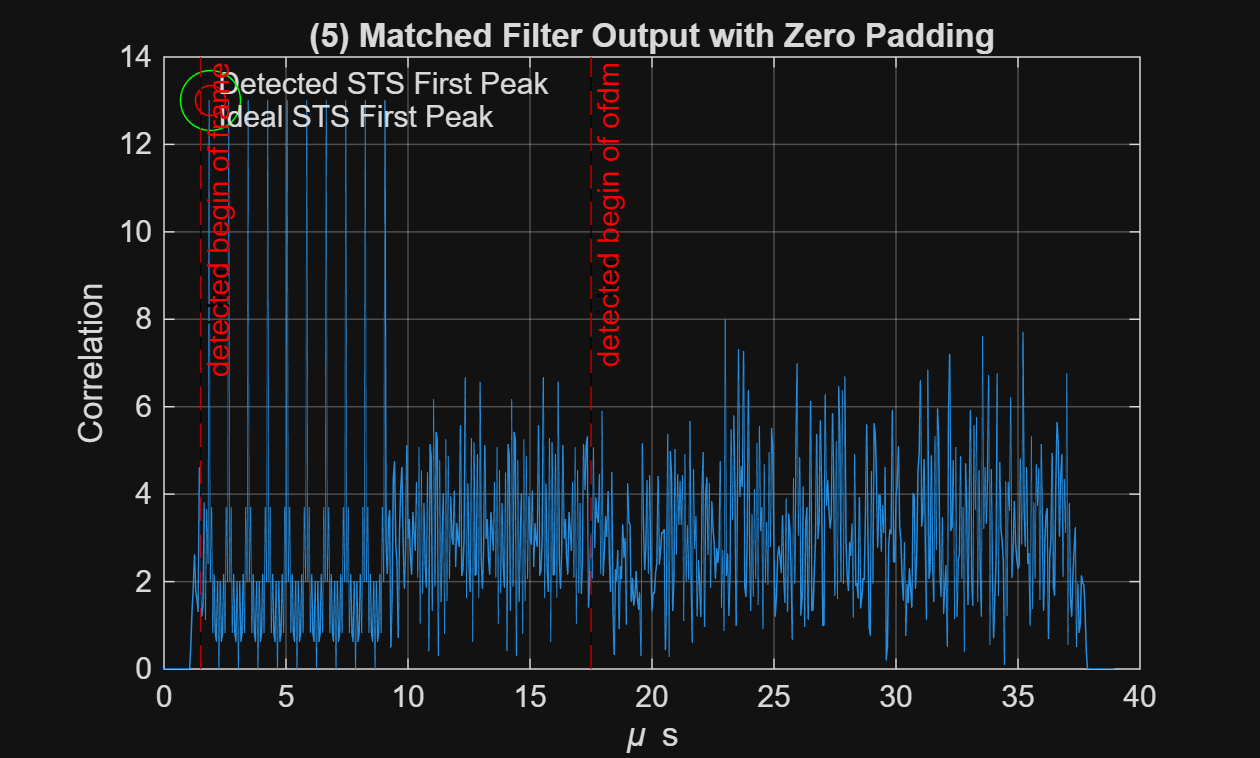

%% (5) Zero-Padded Frame Test
zp_frame = [zeros(1,30), frame, zeros(1,30)];
correlation_zp = abs(conv(zp_frame, mf_sts, 'same'));

[~, original_peak] = max(correlation);
secMax = 0;
for i=1:length(correlation)
    if correlation(i)<max(correlation) && correlation(i) > secMax
        secMax = correlation(i);
    end
end

bound = (max(correlation) + secMax)/2;

peak_idx = 0;
curidx = 1;
while peak_idx == 0 
    if correlation_zp(curidx) > bound
        peak_idx = curidx;
    end
    curidx = curidx+1;
end

% Plot zero-padded result
figure;
t = (0:length(correlation_zp)-1) * (1/20);
plot(t, correlation_zp);
title('(5) Matched Filter Output with Zero Padding'); xlabel('\mu s'); ylabel('Correlation'); grid on;
xline((30)*(1/20), '-k', 'ideal begin of frame');
xline((30 + length(STS_rep)+length(LTS_rep))*(1/20), '-k', 'ideal begin of ofdm');
xline((peak_idx-original_peak)*(1/20), 'r--', 'detected begin of frame');
xline((peak_idx-original_peak + length(STS_rep)+length(LTS_rep))*(1/20), '--r', 'detected begin of ofdm');
hold on;
plot(peak_idx*Ts*1e6, correlation_zp(peak_idx), 'ro', 'MarkerSize', 10);
text(peak_idx*Ts*1e6, correlation_zp(peak_idx), ' Detected STS First Peak', 'VerticalAlignment', 'bottom');

plot((30+original_peak)*Ts*1e6, correlation_zp((30+original_peak)), 'go', 'MarkerSize', 20);
text((30+original_peak)*Ts*1e6, correlation_zp((30+original_peak)), ' Ideal STS First Peak', 'VerticalAlignment', 'top');
hold off;


if peak_idx == 30+original_peak
    fprintf("correctly identify the beginning of the frame and OFDM");
else 
    fprintf("incorrectly identify the beginning of the frame and OFDM");
end

correctly identify the beginning of the frame and OFDM

(6) Following (4), process the 5 OFDM symbols based on the matched filter result and show no error occurs.



signal_start = peak_idx - original_peak +1;% + length(STS_rep) + length(LTS_rep);
retrieved_symbols = zp_frame(signal_start+ length(STS_rep) + length(LTS_rep): numel(OFDM_frame(:))+signal_start+ length(STS_rep) + length(LTS_rep)-1);
error = sum(abs(retrieved_symbols - OFDM_frame(:).')); % Check errors

if (error > 1e-6)
    fprintf("(6) noiseless, detect STS: error detected in OFDM symbols\n");
else 
    fprintf("(6) noiseless, detect STS: no error detected \n");
end

(6) noiseless, detect STS: no error detected 


(7) Following (4), let’s test your algorithm under a noisy channel. As in (5), please start with the

zero-padded frame (30 zeros, followed by STS, LTS, OFDM data, and then 30 zeros). Next,

add white Gaussian noise with 0 dB SNR. Apply your proposed algorithm in (4). Plot the

match filter result and briefly explain the figure. Does your algorithm correctly identify the

beginning of the frame?

the first peak for both ideal and detections are marked on the figure. 

we can observe that the detected peak is correct. -> begin of signal correctly identify

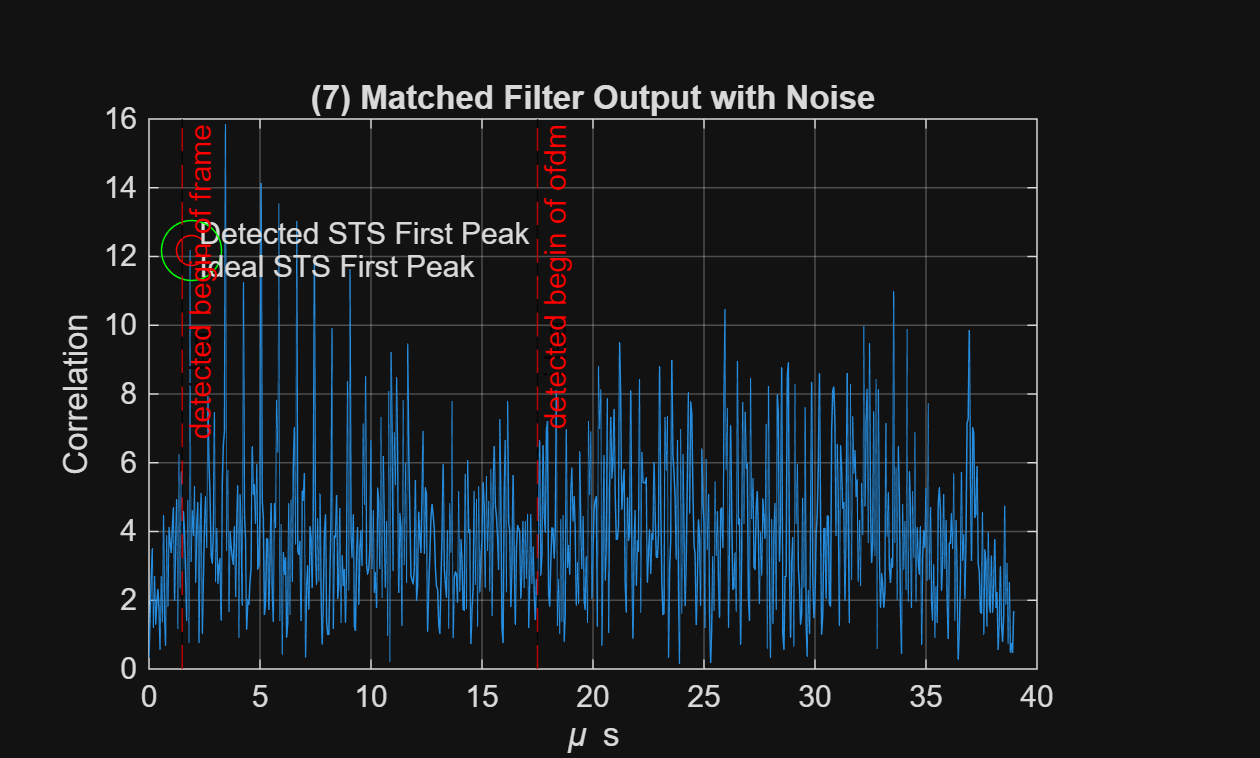

%% (7) Add Noise and Detect Start of Frame
snr_db = 0; % 0 dB SNR
zp_noisy_frame = awgn(zp_frame, snr_db, 'measured');
correlation_zp_noisy = abs(conv(zp_noisy_frame, mf_sts, 'same'));

[~, original_peak] = max(correlation);
secMax = 0;
for i=1:length(correlation)
    if correlation(i)<max(correlation) && correlation(i) > secMax
        secMax = correlation(i);
    end
end

bound = (max(correlation) + secMax)/2;

peak_idx = 0;
curidx = 1;
while peak_idx == 0 
    if correlation_zp_noisy(curidx) > bound
        peak_idx = curidx;
    end
    curidx = curidx+1;
end

% signal_start = peak_idx - original_peak +1;% + length(STS_rep) + length(LTS_rep);
% retrieved_symbols = zp_noisy_frame(signal_start+ length(STS_rep) + length(LTS_rep): numel(OFDM_frame(:))+signal_start+ length(STS_rep) + length(LTS_rep)-1);
% error = sum(abs(retrieved_symbols - OFDM_frame(:).')); % Check errors
% 
% if (error > 1e-6)
%     fprintf("(7) noisy, detect STS: error detected in OFDM symbols,\n sum of error = %f\n", error);
% else 
%     fprintf("(7) noisy, detect STS: no error detected \n");
% end

% Plot correlation with noise
figure;
t = (0:length(correlation_zp_noisy)-1) * (1/20);
plot(t, correlation_zp_noisy);
title('(7) Matched Filter Output with Noise'); xlabel('\mu s'); ylabel('Correlation'); grid on;
% xline((30)*(1/20), '-k', 'ideal begin of frame');
% xline((30 + length(STS_rep)+length(LTS_rep))*(1/20), '-k', 'ideal begin of ofdm');
% xline((peak_idx-original_peak)*(1/20), 'r--', 'detected begin of frame');
hold on;
plot(peak_idx*Ts*1e6, correlation_zp_noisy(peak_idx), 'ro', 'MarkerSize', 10);
text(peak_idx*Ts*1e6, correlation_zp_noisy(peak_idx), ' Detected STS First Peak', 'VerticalAlignment', 'bottom');

plot((30+original_peak)*Ts*1e6, correlation_zp_noisy((30+original_peak)), 'go', 'MarkerSize', 20);
text((30+original_peak)*Ts*1e6, correlation_zp_noisy((30+original_peak)), ' Ideal STS First Peak', 'VerticalAlignment', 'top');
xline((30)*(1/20), '-k', 'ideal begin of frame');
xline((30 + length(STS_rep)+length(LTS_rep))*(1/20), '-k', 'ideal begin of ofdm');
xline((peak_idx-original_peak)*(1/20), 'r--', 'detected begin of frame');
xline((peak_idx-original_peak + length(STS_rep)+length(LTS_rep))*(1/20), '--r', 'detected begin of ofdm');
hold off;

if peak_idx == 30+original_peak
    fprintf("correctly identify the beginning of the frame ");
else 
    fprintf("incorrectly identify the beginning of the frame ");
end

correctly identify the beginning of the frame 

(8) Now, create another matched filter based procedure that detects the long training symbol.

Please explain your synchronization algorithm.

same as (4)

we find the first peak of the correlation signal to align the signal with zp

%% (8) Matched Filter for LTS Detection
mf_lts = conj(flip(LTS_time));
correlation_lts = abs(conv(frame, mf_lts, 'same'));
correlation_lts_zp = abs(conv(zp_frame, mf_lts, 'same'));



[~, original_peak] = max(correlation_lts);
secMax = 0;
for i=1:length(correlation_lts)
    if correlation_lts(i)<max(correlation_lts) && correlation_lts(i) > secMax
        secMax = correlation_lts(i);
    end
end

bound = (max(correlation_lts) + secMax)/2;

peak_idx = 0;
curidx = 1;
while peak_idx == 0 
    if correlation_lts_zp(curidx) > bound
        peak_idx = curidx;
    end
    curidx = curidx+1;
end

signal_start = peak_idx - original_peak +1;% + length(STS_rep) + length(LTS_rep);
retrieved_symbols = zp_frame(signal_start+ length(STS_rep) + length(LTS_rep): numel(OFDM_frame(:))+signal_start+ length(STS_rep) + length(LTS_rep)-1);
error = sum(abs(retrieved_symbols - OFDM_frame(:).')); % Check errors

if (error > 1e-6)
    fprintf("(8) noiseless, detect lts: error detected in OFDM symbols,\n sum of error = %f\n", error);
else 
    fprintf("(8) noiseless, detect lts: no error detected \n");
end

(8) noiseless, detect lts: no error detected 


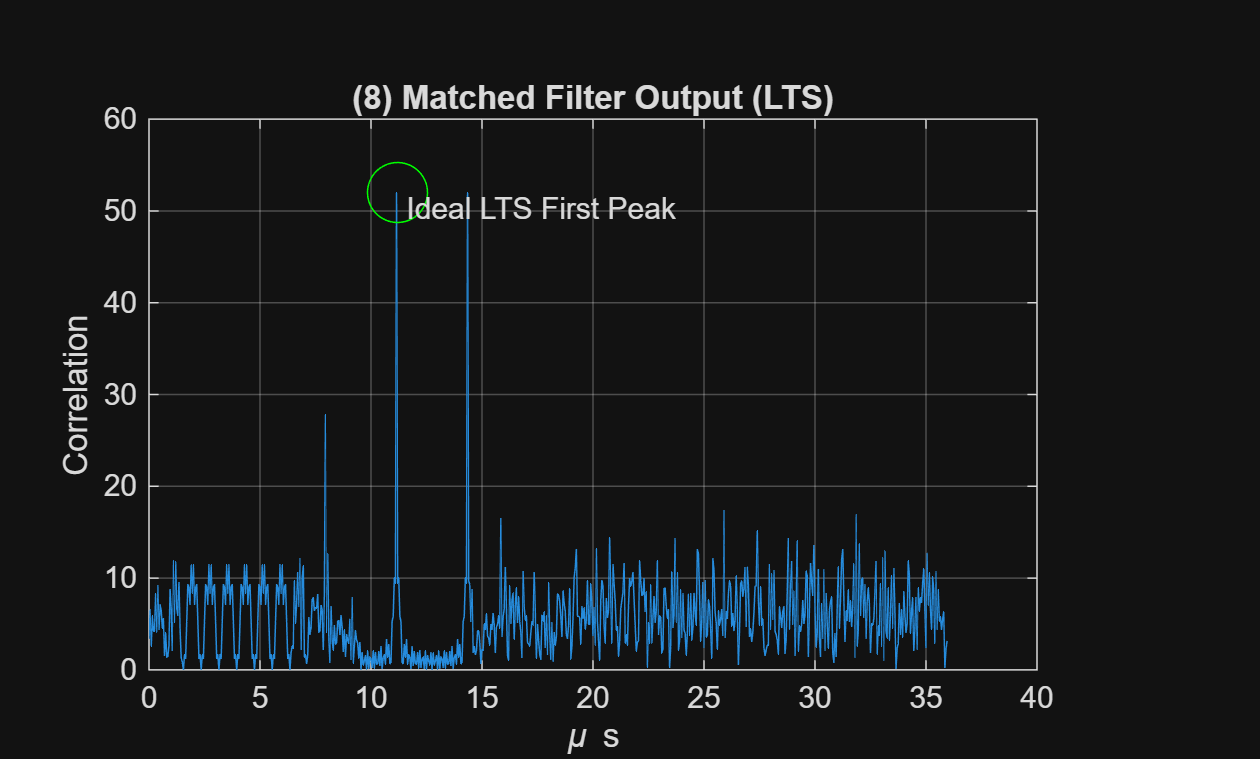




% Plot LTS detection
figure;
t = (0:length(correlation_lts)-1) * (1/20);
plot(t, correlation_lts);
title('(8) Matched Filter Output (LTS)'); xlabel('\mu s'); ylabel('Correlation'); grid on;
hold on;
plot((original_peak)*Ts*1e6, correlation_lts((original_peak)), 'go', 'MarkerSize', 20);
text((original_peak)*Ts*1e6, correlation_lts((original_peak)), ' Ideal LTS First Peak', 'VerticalAlignment', 'top');
hold off;

(9) Similar to (7), but now use your proposed algorithm in (8). Plot the match filter result and

briefly explain the figure. Does your algorithm correctly identify the beginning of the frame?

the first peak for both ideal and detections are marked on the figure. 

we can observe that the detected peak is correct -> begin of signal correctly identify

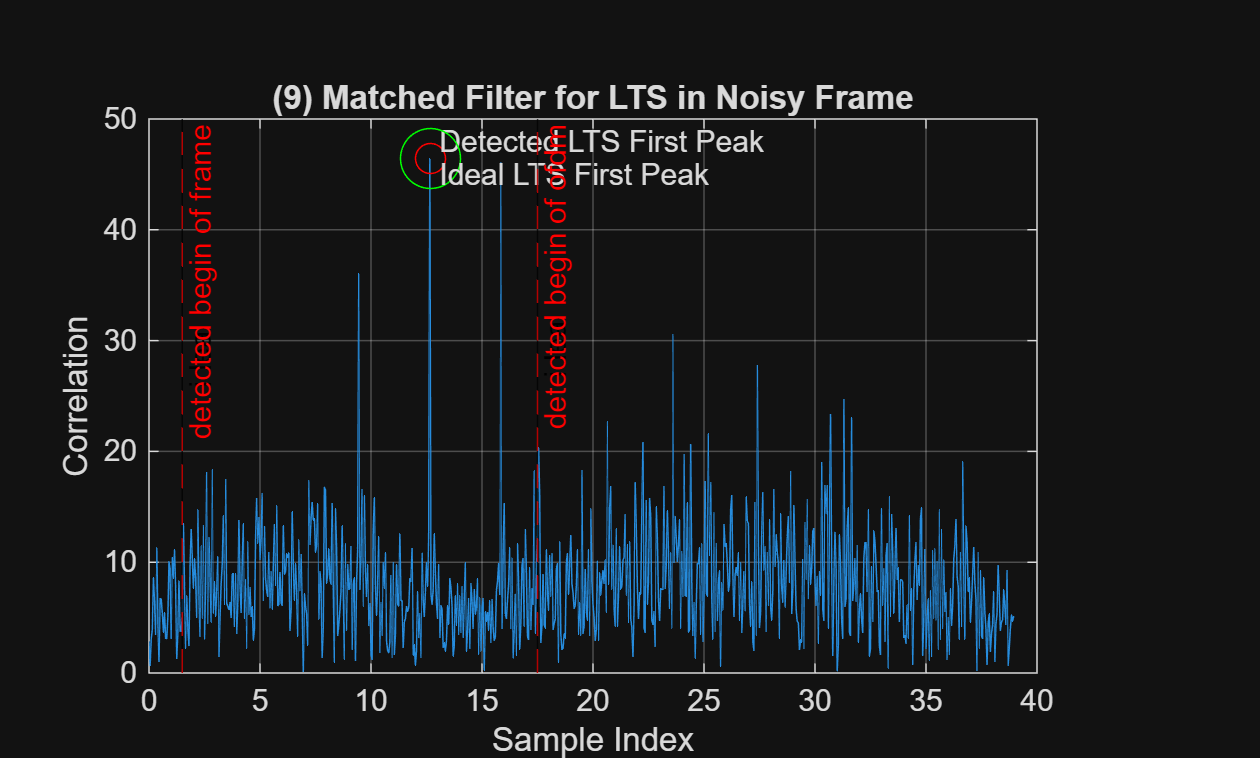

correlation_lts_noisy = abs(conv(zp_noisy_frame, mf_lts, 'same'));


[~, original_peak] = max(correlation_lts);
secMax = 0;
for i=1:length(correlation_lts)
    if correlation_lts(i)<max(correlation_lts) && correlation_lts(i) > secMax
        secMax = correlation_lts(i);
    end
end

bound = (max(correlation_lts) + secMax)/2;

peak_idx = 0;
curidx = 1;
while peak_idx == 0 
    if correlation_lts_noisy(curidx) > bound
        peak_idx = curidx;
    end
    curidx = curidx+1;
end

% signal_start = peak_idx - original_peak +1;% + length(STS_rep) + length(LTS_rep);
% retrieved_symbols = zp_noisy_frame(signal_start+ length(STS_rep) + length(LTS_rep): numel(OFDM_frame(:))+signal_start+ length(STS_rep) + length(LTS_rep)-1);
% error = sum(abs(retrieved_symbols - OFDM_frame(:).')); % Check errors
% 
% if (error > 1e-6)
%     fprintf("(9) noisy, detect lts: error detected in OFDM symbols,\n sum of error = %f\n", error);
% else 
%     fprintf("(9) noisy, detect lts: no error detected \n");
% end


figure;
t = (0:length(correlation_lts_noisy)-1) * (1/20);
plot(t, correlation_lts_noisy);
title('(9) Matched Filter for LTS in Noisy Frame'); xlabel('Sample Index'); ylabel('Correlation'); grid on;

hold on;
plot(peak_idx*Ts*1e6, correlation_lts_noisy(peak_idx), 'ro', 'MarkerSize', 10);
text(peak_idx*Ts*1e6, correlation_lts_noisy(peak_idx), ' Detected LTS First Peak', 'VerticalAlignment', 'bottom');

plot((30+original_peak)*Ts*1e6, correlation_lts_noisy((30+original_peak)), 'go', 'MarkerSize', 20);
text((30+original_peak)*Ts*1e6, correlation_lts_noisy((30+original_peak)), ' Ideal LTS First Peak', 'VerticalAlignment', 'top');

xline((30)*(1/20), '-k', 'ideal begin of frame');
xline((30 + length(STS_rep)+length(LTS_rep))*(1/20), '-k', 'ideal begin of ofdm');
xline((peak_idx-original_peak)*(1/20), 'r--', 'detected begin of frame');
xline((peak_idx-original_peak + length(STS_rep)+length(LTS_rep))*(1/20), '--r', 'detected begin of ofdm');
hold off;


if peak_idx == 30+original_peak
    fprintf("correctly identify the beginning of the frame ");
else 
    fprintf("incorrectly identify the beginning of the frame ");
end

correctly identify the beginning of the frame 

10. Compare the results in (7) and (9). What do you observe and why?

we can detect either sts and lts with different match filters, with an appropriate design and algorithm, we can successfully detect the start of signal mostly.

不過有時候sts detection 比lts容易失敗。因為sts的peak 沒有lts的高，所以在detect sts的時候較容易會誤判first peak。

但上面的code只會跑測試一次，所以要多按幾次才會發現。

(11) Simulate LoS(attenuation 0.4, delay 0) & NLoS(attenuation 0.3, delay 0.5 us) and plot

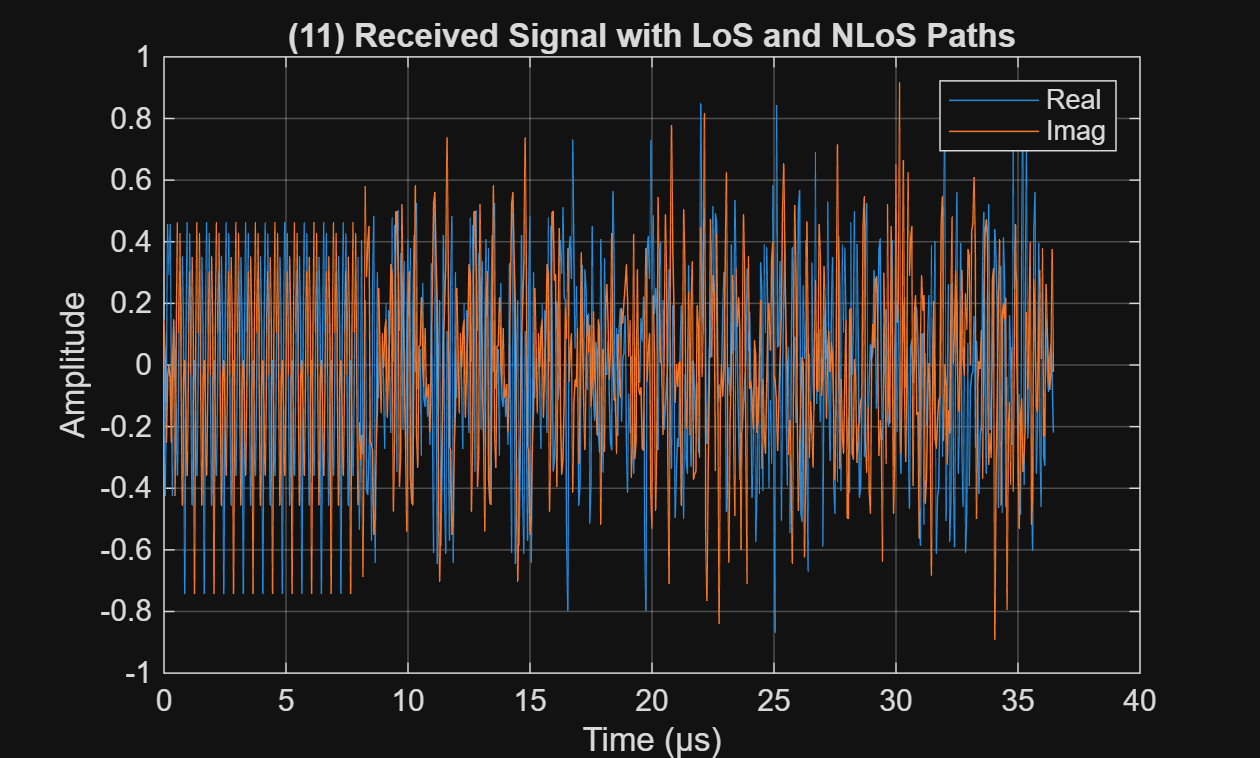

delay_us = 0.5;  % 0.5 μs delay for NLoS
delay_samples = round(delay_us * 1e-6 / Ts);
h_los = 0.4; 
h_nlos = 0.3;

% Two-path channel impulse response
h = zeros(1, delay_samples+1);
h(1) = h_los;
h(end) = h_nlos;

% Convolve with frame
rx_channel = conv(frame, h, 'full');

% Time axis for plotting (μs)
t = (0:length(rx_channel)-1) * Ts * 1e6;

figure;
plot(t, real(rx_channel)); hold on;
plot(t, imag(rx_channel));
xlabel('Time (μs)'); ylabel('Amplitude');
title('(11) Received Signal with LoS and NLoS Paths');
legend('Real','Imag');
grid on;

(12) Imperfect time synchronization: receiver starts at t = 0.2 us

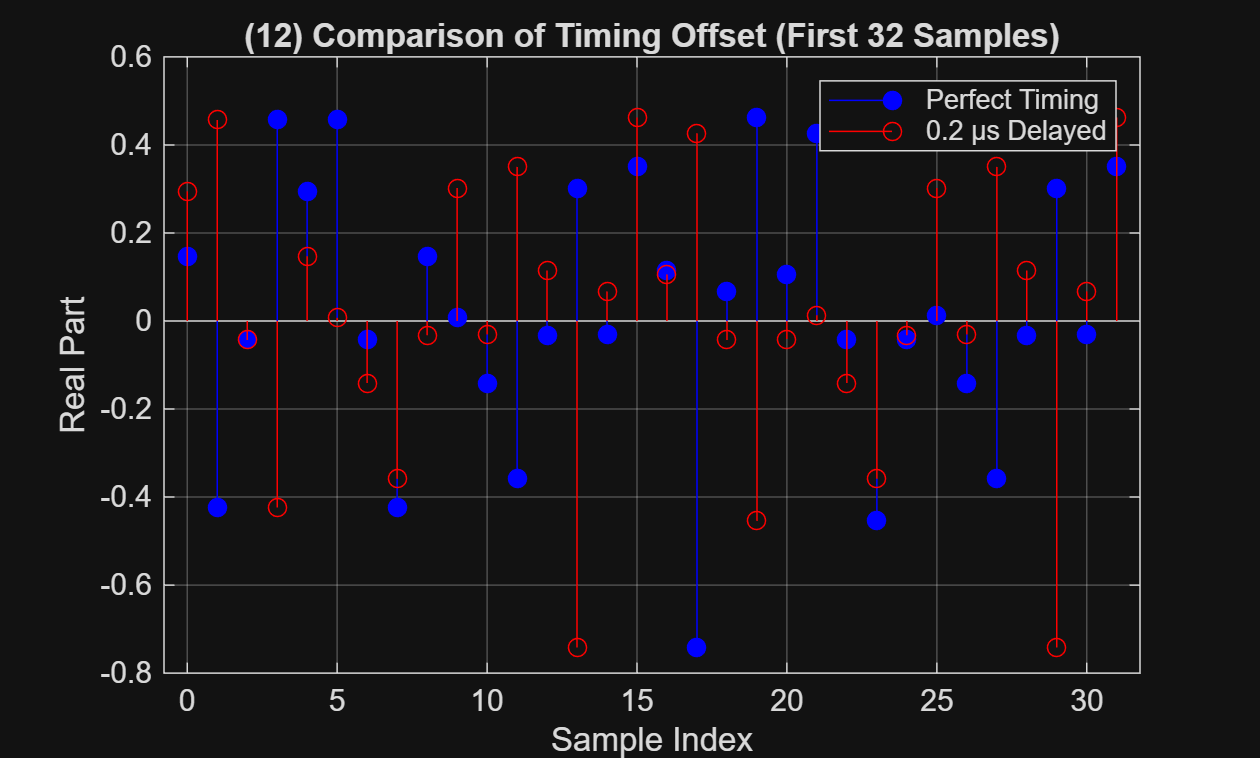

offset_us = 0.2;
offset_samples = round(offset_us * 1e-6 / Ts);
rx_shifted = rx_channel(1+offset_samples:end);

n_plot = 32;
figure;
stem(0:(n_plot-1), real(rx_channel(1:n_plot)), 'b', 'filled'); hold on;
stem(0:(n_plot-1), real([rx_shifted(1:n_plot), zeros(1, max(0, n_plot-length(rx_shifted)))]), 'r');
xlabel('Sample Index'); ylabel('Real Part');
legend('Perfect Timing','0.2 μs Delayed');
title('(12) Comparison of Timing Offset (First 32 Samples)');
grid on;

fprintf('(12) Receiver delay = %d samples (%.2f μs)\n', offset_samples, offset_us);

(12) Receiver delay = 4 samples (0.20 μs)


(13) Use matched filter on LTS to find STS/LTS/OFDM parts (assumes known lts_time_domain)

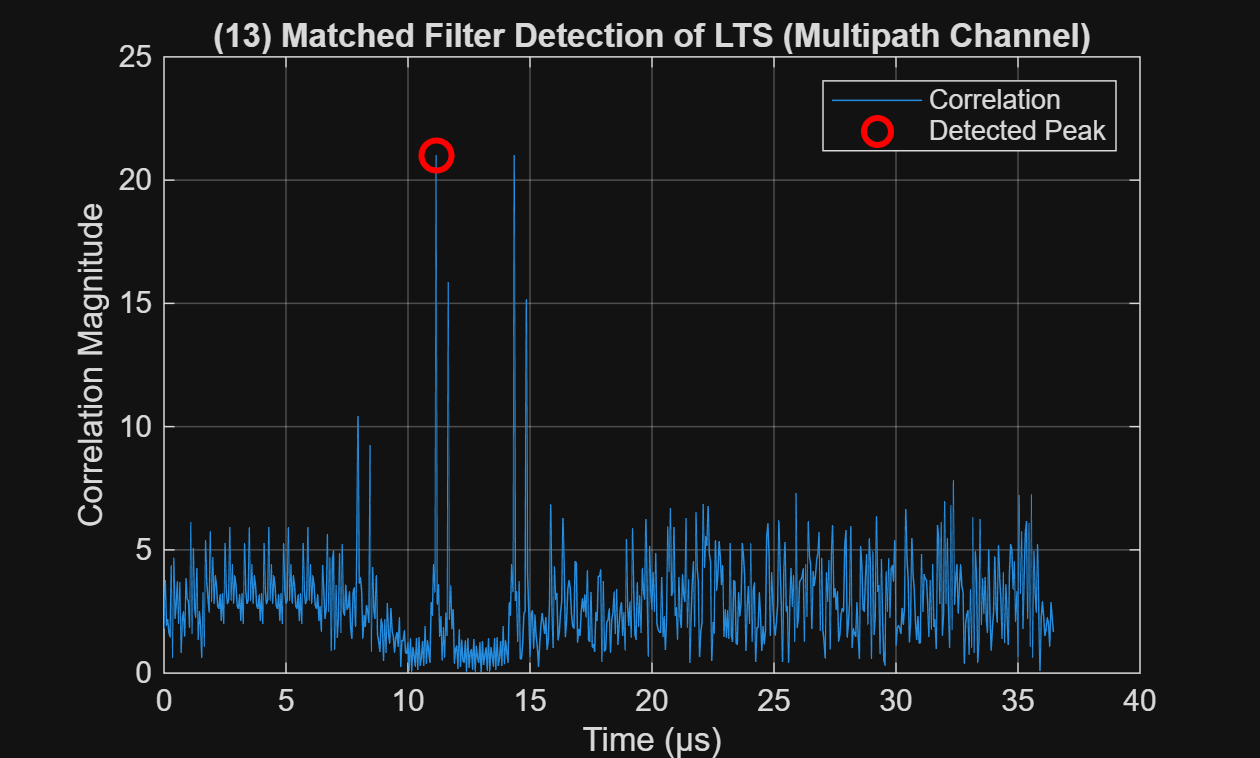

mf_lts = conj(flip(LTS_time)); % reuse LTS_time from (2)
correlation_lts_multipath = abs(conv(rx_channel, mf_lts, 'same'));

[~, lts_peak] = max(correlation_lts_multipath);
lts_start = lts_peak - length(LTS_time) + 1;

t_corr = (0:length(correlation_lts_multipath)-1) * Ts * 1e6;
figure;
plot(t_corr, correlation_lts_multipath);
hold on;
plot(t_corr(lts_peak), correlation_lts_multipath(lts_peak), 'ro', 'MarkerSize', 10, 'LineWidth',2);
xlabel('Time (μs)');
ylabel('Correlation Magnitude');
title('(13) Matched Filter Detection of LTS (Multipath Channel)');
legend('Correlation','Detected Peak');
grid on;

fprintf('(13) Detected LTS start ≈ %.3f μs\n', lts_start*Ts*1e6);

(13) Detected LTS start ≈ 8.050 μs


(14) Channel estimation using LTS

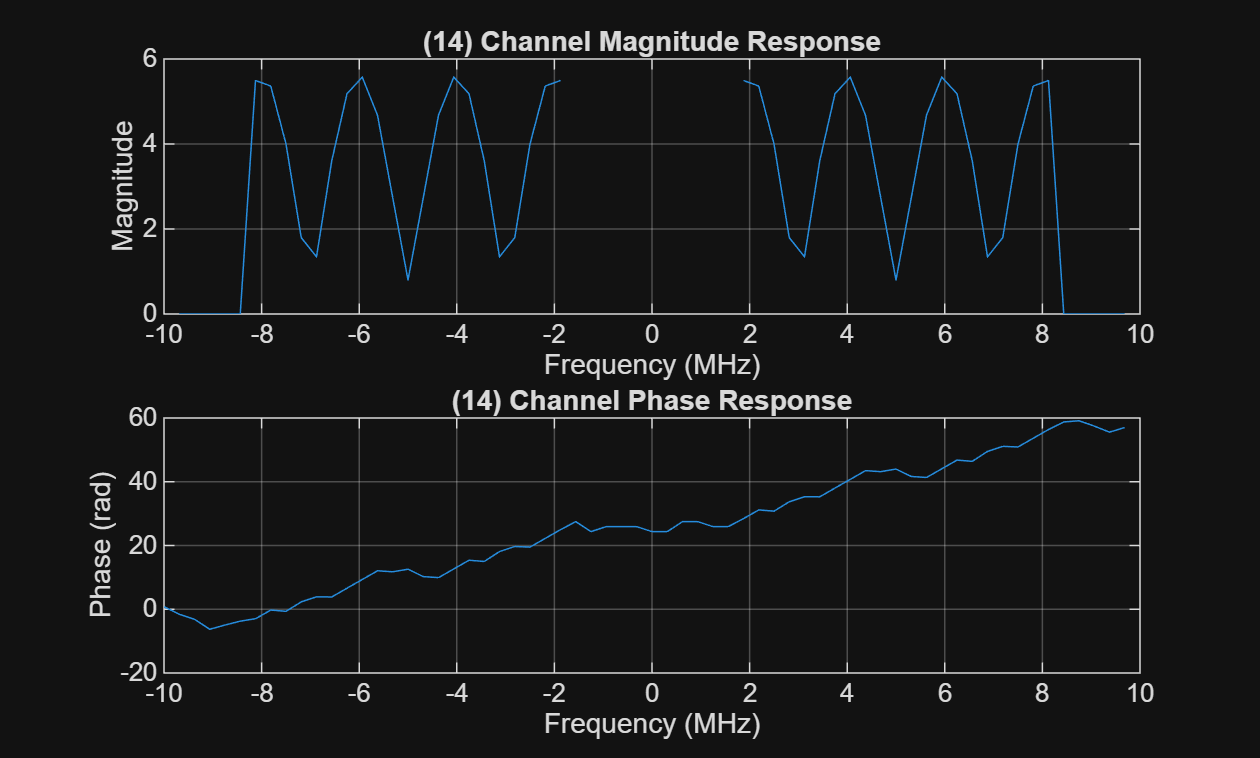

LTS_symbol_len = N;
LTS_cp_len = 32; % per 802.11 spec
start_idx = lts_start + LTS_cp_len;
rx_lts1 = rx_channel(start_idx:start_idx+N-1);
rx_lts2 = rx_channel(start_idx+N:start_idx+2*N-1);
RX_LTS1 = fft(rx_lts1);
RX_LTS2 = fft(rx_lts2);
RX_LTS = (RX_LTS1 + RX_LTS2)/2;

% Known LTS freq pattern (reuse from (2))
LTS_freq_ref = LTS_freq;
H_est = RX_LTS ./ LTS_freq_ref(:).';

% Frequency axis in MHz
freq_axis = ((-N/2):(N/2-1)) * (Fs/N) / 1e6;

figure;
subplot(2,1,1);
plot(freq_axis, abs(fftshift(H_est)));
xlabel('Frequency (MHz)'); ylabel('Magnitude');
title('(14) Channel Magnitude Response');
grid on;

subplot(2,1,2);
plot(freq_axis, unwrap(angle(fftshift(H_est))));
xlabel('Frequency (MHz)'); ylabel('Phase (rad)');
title('(14) Channel Phase Response');
grid on;

(15) Describe the estimated channel (printed)

fprintf(['(15) Observations:\n', ...
    '- Channel shows frequency-dependent amplitude and phase due to two-path interference.\n', ...
    '- The two-path delays will produce a sinusoidal-like frequency response (not flat) because NLoS introduces frequency-selective fading.\n']);

(15) Observations:
- Channel shows frequency-dependent amplitude and phase due to two-path interference.
- The two-path delays will produce a sinusoidal-like frequency response (not flat) because NLoS introduces frequency-selective fading.


(16) Equalize received OFDM symbols using H_est, plot constellation before/after

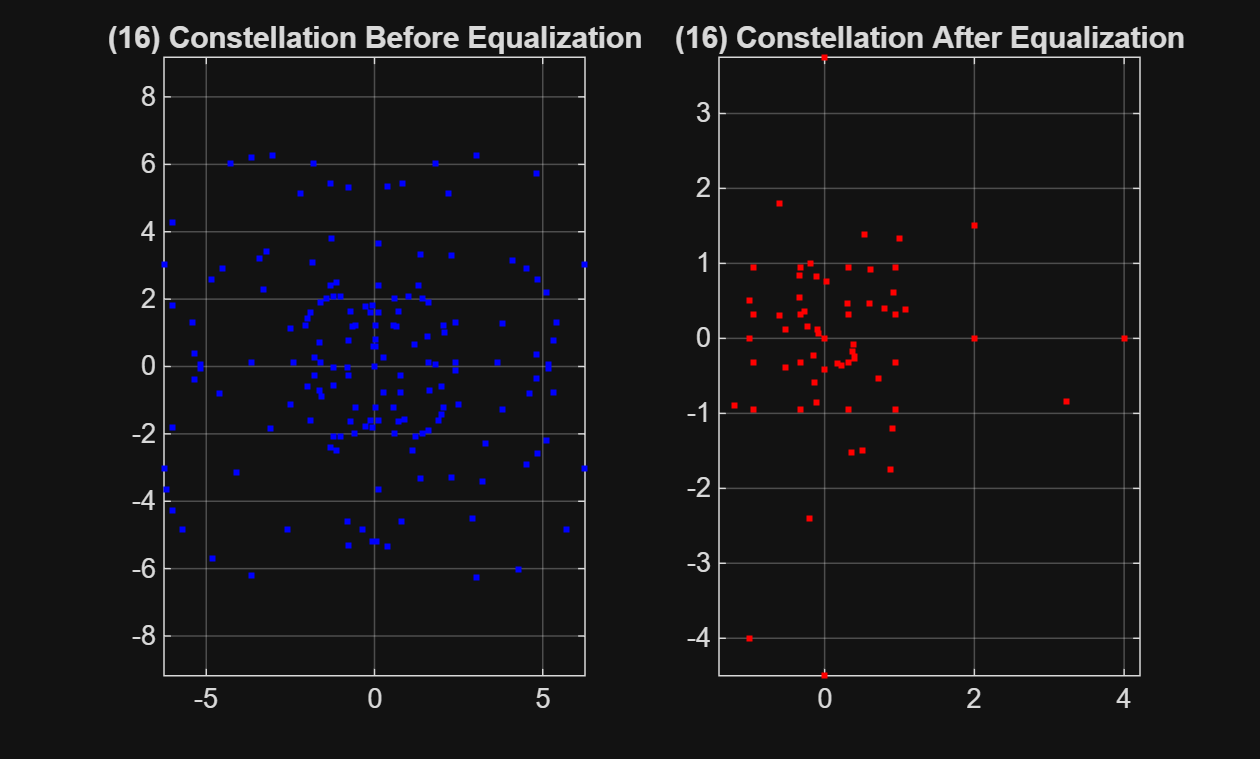

data_start = lts_start + length(LTS_rep);
rx_data_section = rx_channel(data_start:end);

% Extract 5 OFDM symbols
symbol_len = N + 16;
rx_symbols_time = reshape(rx_data_section(1:symbol_len*5), symbol_len, 5);

const_before = [];
const_after = [];

for k = 1:5
    rx_symbol_nocp = rx_symbols_time(CP+1:end, k);
    RX_symbol = fft(rx_symbol_nocp);
    EQ_symbol = RX_symbol ./ H_est(:);
    const_before = [const_before; RX_symbol(index).']; %#ok<AGROW>
    const_after = [const_after; EQ_symbol(index).']; %#ok<AGROW>
end

figure;
subplot(1,2,1);
plot(real(const_before), imag(const_before), 'b.');
axis equal; grid on;
title('(16) Constellation Before Equalization');

subplot(1,2,2);
plot(real(const_after), imag(const_after), 'r.');
axis equal; grid on;
title('(16) Constellation After Equalization');

(17) Demodulate equalized constellation and check errors

rx_bits = qamdemod(const_after, M, 'UnitAveragePower', true, 'OutputType','bit');
tx_bits = qamdemod(OFDM_freq(index,:), M, 'UnitAveragePower', true, 'OutputType','bit');

nbits = min(numel(tx_bits), numel(rx_bits));
num_errors = sum(rx_bits(1:nbits) ~= tx_bits(1:nbits));
BER_est = num_errors / nbits;
fprintf('(17) Bit errors = %d / %d, BER = %.4e\n', num_errors, nbits, BER_est);

(17) Bit errors = 497 / 1060, BER = 4.6887e-01


if BER_est < 1e-6
    disp('(17) Perfect recovery achieved (no bit errors).');
else
    disp('(17) Some residual errors — check alignment or H_est normalization.');
end

(17) Some residual errors — check alignment or H_est normalization.
